# Identification of linear system from sampled data - lab 2

## Load data for identification

clear all
clc
load("dataidentlab2.mat");
Tprbs = Ts*(0:length(uprbs)-1);
%plot(Tprbs,uprbs,Tprbs,yprbs);title('response of the system to a PRBS excitation signal');
T211 = Ts*(0:length(u211)-1);
%plot(T211,u211,T211,y211);title('response of the system to a 211 excitation signal');
Tstep = Ts*(0:length(ustep)-1);
%plot(Tstep,ustep,Tstep,ystep);title('response of the system to a step input');

## **Identification Processs**

**1) PRBS INPUT**

First we consider **Pseudorandom binary sequence(**PRBS) excitation to perform system identification.

u = uprbs;
y = yprbs;
t = Tprbs;
%Data preparation
N = length(u);
uident = u(1:N/2);
yident = y(1:N/2);
uvalid = u(N/2:end);
yvalid = y(N/2:end);
%Evaluate delay - using impulse response
[A,B] = RLS(uident,yident,0,50,0);
%stem(B)
for i=1:length(B)
    if abs(B(i))>0.04    
       nk=(i-1)-1
       break
   end
end

nk = 3

We calculate delay with the help of the Finite Impulse Response method, by giving a unit impulse as input to force y(t)=b0+b1+b2+.... . Thus, when we observe the residual of the B vector, we calculate the delay in response. We have calculated nk = (i-1) -1 for two reasons. Firstly we consider (i-1) as the value of i starts from 1. Further we subtract 1 from (i-1) since the first value of B vector can not be calculated due to lack of initial values.

%Identification of a discrete time model
[order1_prbs,AIC1_prbs] = RLSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid);

discrete_time_model_RLS =
 
  -0.06973 z^-4 - 0.06491 z^-5 + 0.07439 z^-6 + 0.1978 z^-7 + 0.1987 z^-8 + 0.1109 z^-9 + 0.02747 z^-10
  -----------------------------------------------------------------------------------------------------
  1 - 0.04537 z^-1 + 0.0431 z^-2 + 0.05664 z^-3 + 0.03506 z^-4 - 0.121 z^-5 - 0.2338 z^-6 - 0.2487 z^-7
 
Sample time: 0.1 seconds
Discrete-time transfer function.



minimum_AIC = -6.2754

na = 7

nb = 7

nk = 3

[order2_prbs,AIC2_prbs] = ELSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid);

From these results, we can see that the results and the final models given by both RLS and ELS algorithms have more or less similar order of the systems (na = nb = 7). Since, the AIC value does not differ much, the model obtained from the RLS algorithm is sufficient to identify the model as the disturbance is similar to white noise in this case.

We also see both algorithms give similar trends of residuals ranging between the bandwidth of -0.1 to 0.1.

**2) 211 INPUT**

u = u211;
y = y211;
t = T211;
%Data preparation
N = length(u);
uident = u(1:N/2);
yident = y(1:N/2);
uvalid = u(N/2:end);
yvalid = y(N/2:end);
%Evaluate delay - using impulse response
[A,B] = RLS(uident,yident,0,50,0);
%stem(B)
for i=1:length(B)
    if abs(B(i))>0.04    
       nk=(i-1)-1
       break
   end
end

nk = 3

%Identification of a discrete time model
[order1_211,AIC1_211] = RLSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid);

discrete_time_model_RLS =
 
  -0.06854 z^-4 - 0.06003 z^-5 + 0.08377 z^-6 + 0.1935 z^-7 + 0.1812 z^-8 + 0.08783 z^-9 + 0.005779 z^-10 - 0.01859 z^-11 - 0.007577 z^-12
  ----------------------------------------------------------------------------------------------------------------------------------------
   1 - 0.1412 z^-1 - 0.006997 z^-2 + 0.05696 z^-3 - 0.005902 z^-4 - 0.139 z^-5 - 0.2218 z^-6 - 0.1744 z^-7 - 0.03412 z^-8 + 0.06378 z^-9
 
Sample time: 0.1 seconds
Discrete-time transfer function.



minimum_AIC = -37.3880

na = 9

nb = 9

nk = 3

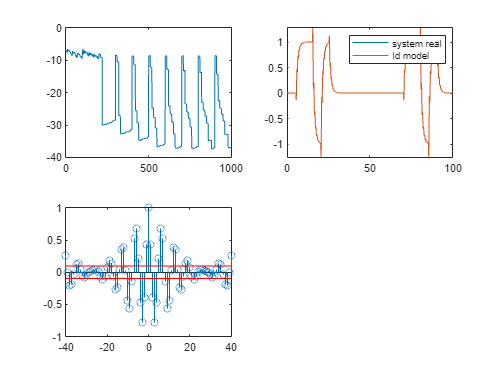

discrete_time_model_ELS =
 
  -0.06854 z^-4 - 0.06003 z^-5 + 0.08377 z^-6 + 0.1935 z^-7 + 0.1812 z^-8 + 0.08783 z^-9 + 0.005779 z^-10 - 0.01859 z^-11 - 0.007577 z^-12
  ----------------------------------------------------------------------------------------------------------------------------------------
   1 - 0.1412 z^-1 - 0.006997 z^-2 + 0.05696 z^-3 - 0.005902 z^-4 - 0.139 z^-5 - 0.2218 z^-6 - 0.1744 z^-7 - 0.03412 z^-8 + 0.06378 z^-9
 
Sample time: 0.1 seconds
Discrete-time transfer function.



minimum_AIC = -37.3840

na = 9

nb = 9

nc = 1

nk = 3

[order2_211,AIC2_211] = ELSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid);

In the 211 excitation case, the high order of the system in both RLS and ELS cases are observed (na=nb=9) as well as the low AIC = -37. However, this will result in a large variance in the system identification. We observe high autocorrelation from the stem graphs which indicates that the identified system is misrepresented.

**3) STEP INPUT**

u = ustep;
y = ystep;
t = Tstep;
%Data preparation
N = length(u);
uident = u(1:N/2);
yident = y(1:N/2);
uvalid = u(N/2:end);
yvalid = y(N/2:end);
%Evaluate delay - using impulse response
[A,B] = RLS(uident,yident,0,50,0);
%stem(B)
for i=1:length(B)
    if abs(B(i))>0.04    
       nk=(i-1)-1
       break
   end
end

nk = 1

%Identification of a discrete time model
[order1_step,AIC1_step] = RLSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid);

discrete_time_model_RLS =
 
                                                                                                                                                
  0.06681 z^-2 - 0.1618 z^-3 + 0.04591 z^-4 - 0.1232 z^-5 + 0.1959 z^-6 + 0.1387 z^-7 + 0.2334 z^-8 - 0.1311 z^-9 - 0.0588 z^-10 - 0.04966 z^-11
                                                                                                                                                
                                                                                                                                                
  ----------------------------------------------------------------------------------------------------------------------------------------------
                                                                                               
                                                  1 - 0.5223 z^-1 - 0.001132 z^-2 - 0.3164 z^-3
                                                       

minimum_AIC = -6.0892

na = 3

nb = 10

nk = 1

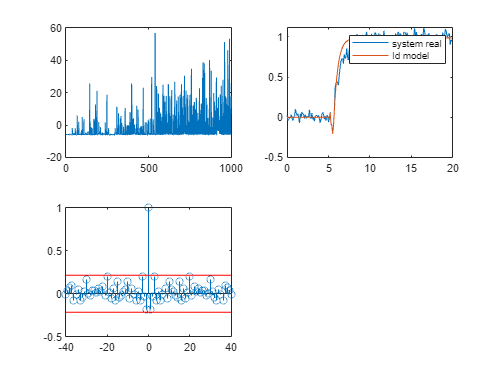

discrete_time_model_ELS =
 
  0.05915 z^-2 - 0.194 z^-3 + 0.1051 z^-4 - 0.09443 z^-5 + 0.1806 z^-6 + 0.1067 z^-7 + 0.02237 z^-8
  -------------------------------------------------------------------------------------------------
                                           1 - 0.8116 z^-1
 
Sample time: 0.1 seconds
Discrete-time transfer function.



minimum_AIC = -6.1408

na = 1

nb = 7

nc = 2

nk = 1

[order2_step,AIC2_step] = ELSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid);

In this case, the ELS generated model is clearly better (na = 1 ; nb = 7 ; nc = 2 ; nk = 1) as compared to the RLS case (na = 3 ; nb = 10 ; nk = 1). We observe a lower AIC with a lower order of the system as well In case of a step response, we cannot consider disturbances to be simply white noise.

### Conclusion

After trying different excitation signals, we conclude that the prbs signal is the best for the following reasons -

1) We have the low AIC = -6.35 compared to the step input (the 211 case is misrepresented).

2) The residuals show the lowest bandwidth of -0.1 to 0.1 compared to the step input (-0.2 to 0.2).

3) In the prbs case, the RLS is sufficient which takes lesser computation time to identify the model since the disturbance is comparable to white noise.

## **FUNCTIONS**

**1) RLS ALGORITHM IDENTIFICATION**

function [order,minimum_AIC] = RLSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid)
RLSerrors = [];     %initializing a list to store errors 
RLSsysids = [];     %initializing a list to store system model 
RLSAICs = [];       %initializing a list to store AIC value 
RLSparams = [];     %initializing a list to store parameters na,nb,nk 
for na=1:10           %initializing the loop for parameters na and nb considering from 1 to 10          
    for nb = 1:10
            RLSparams = [RLSparams ; [na nb nk]];   %assigning paramters to the list
            [A,B] = RLS(uident,yident,na,nb,nk);            %solving using RLS algorithm
            [err, J, AIC] = computerrors(uvalid,yvalid,A,B,[]);      %computing the erros and applying AIC criteria
            sysid = tf(B,A,Ts,'variable','z^-1');       %obtainig the tranfer function
            RLSerrors = [RLSerrors ; err'];     %appending obtained error to the list
            RLSAICs(end+1) = AIC;          %appending obtained AIC to the list
            RLSsysids = [RLSsysids ; sysid];    %appending obtained system model to the list
    end
end

%Validation
figure(1);
subplot(2,2,1);
plot([1:na*nb],RLSAICs)   %plot to observe the trend of all AICs
[minimum_AIC,i] = min(RLSAICs);   %collecting minimun AIC value among all computed system ids
discrete_time_model_RLS = RLSsysids(i)    %collecting the system model of the best system with least AIC
minimum_AIC
na = RLSparams(i,1)
nb = RLSparams(i,2)       %observing the parameters at minimum AIC
nk = RLSparams(i,3)
ysim1 = lsim(discrete_time_model_RLS,u,t);  %Simulating the output for our identified model

subplot(2,2,2);
plot(t,y,t,ysim1)     %observing the difference bw simulated and given output
legend('system real','Id model');
order = [na nb 0];

%Analyse residuals
N1= length(uvalid);
x1 = xcorr(RLSerrors(i,:),RLSerrors(i,:));   %finding correlation
x1 = x1/x1(N1); %nomalizing the correlation
subplot(2,2,3);
stem(-40:1:40,x1(N1-40:N1+40));    %observing the residual graph for chosen model
line([-40 40],[2.17/sqrt(N1) 2.17/sqrt(N1)],'color','r');
line([-40 40],[-2.17/sqrt(N1) -2.17/sqrt(N1)],'color','r');
hold off
end


**2) ELS ALGORITHM IDENTIFICATION**

function [order,minimum_AIC] = ELSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid)
ELSerrors = [];          %initializing a list to store errors 
ELSsysids = [];         %initializing a list to store system model 
ELSAICs = [];             %initializing a list to store AIC value 
ELSparams = [];        %initializing a list to store parameters na,nb,nc,nk 
for na=1:10
    for nb = 1:10           %initializing the loop for parameters na, nb and nc considering from 1 to 10  
        for nc = 1:10
                ELSparams = [ELSparams ; [na nb nc nk]];      %assigning paramters to the list
                [A,B,C] = ELS(uident,yident,na,nb,nc,nk);        %solving using ELS algorithm
                [err, J, AIC] = computerrors(uvalid,yvalid,A,B,C);          %computing the erros and applying AIC criteria
                sysid = tf(B,A,Ts,'variable','z^-1');           %obtainig the tranfer function
                ELSerrors = [ELSerrors ; err'];             %appending obtained error to the list
                ELSAICs(end+1) = AIC;               %appending obtained AIC to the list
                ELSsysids = [ELSsysids ; sysid];             %appending obtained system model to the list
        end
    end
end

%Validation
figure(2)
subplot(2,2,1);
plot([1:na*nb*nc],ELSAICs)   %plot to observe the trend of all AICs
[minimum_AIC,i] = min(ELSAICs);          %collecting minimun AIC value among all computed system ids
discrete_time_model_ELS = ELSsysids(i)       %collecting the system model of the best system with least AIC
minimum_AIC
na = ELSparams(i,1)
nb = ELSparams(i,2)
nc = ELSparams(i,3)         %observing the parameters at minimum AIC
nk = ELSparams(i,4)
ysim2 = lsim(discrete_time_model_ELS,u,t);    %Simulating the output for our identified model
subplot(2,2,2);
plot(t,y,t,ysim2)            %observing the difference bw simulated and given output
legend('system real','Id model');
order = [na nb nc];

%Analyse residuals
N2 = length(uvalid);
x2 = xcorr(ELSerrors(i,:),ELSerrors(i,:));           %finding correlation
x2 = x2/x2(N2);              %nomalizing the correlation
subplot(2,2,3);
stem(-40:1:40,x2(N2-40:N2+40));                 %observing the residual graph for chosen model
line([-40 40],[2.17/sqrt(N2) 2.17/sqrt(N2)],'color','r');
line([-40 40],[-2.17/sqrt(N2) -2.17/sqrt(N2)],'color','r');
end

### 3) Recursive Least Square Algorithms

function [A,B] = RLS(uid,yid,na,nb,nk)
uid = reshape(uid,[],1);
yid = reshape(yid,[],1);
%initialization
theta = zeros(na+nb,1);
D = 10^6*eye(na+nb);
%Recursive algorithm
for t = max([na nb+nk]):(length(yid)-1)
    phi = [-yid(t:-1:t-na+1);uid(t-nk:-1:t-nb-nk+1)];
    yhatprior = theta'*phi;
    eps0 = yid(t+1)-yhatprior;
    epsposterior = eps0/(1+phi'*D*phi);
    theta = theta + D*phi*epsposterior;
    D = D - D*phi*phi'*D/(1+phi'*D*phi);
end
A = [1;theta(1:na)]';
B = [zeros(nk+1,1);theta(na+1:na+nb)]';
end

### 4) Recursive Extended Least Square Algorithm

function [A,B,C] = ELS(uid,yid,na,nb,nc,nk)
uid = reshape(uid,[],1);
yid = reshape(yid,[],1);
%initialization
theta = zeros(na+nb+nc,1);
D = 10^6*eye(na+nb+nc);
epsposterior = zeros(length(yid),1);
eps0 = zeros(length(yid),1);
%Recursive algorithm
for t = max([na nb+nk nc]):(length(yid)-1)
    phi = [-yid(t:-1:t-na+1);uid(t-nk:-1:t-nb-nk+1);epsposterior(t:-1:t-nc+1)];
    yhatprior = theta'*phi;
    eps0(t+1) = yid(t+1)-yhatprior;
    epsposterior(t+1) = eps0(t+1)/(1+phi'*D*phi);
    theta = theta + D*phi*epsposterior(t+1);
    D = D - D*phi*phi'*D/(1+phi'*D*phi);
end

A = [1;theta(1:na)]';
B = [zeros(nk+1,1);theta(na+1:na+nb)]';
C = theta(na+nb+1:end)';
end

### 5) Prediction Error and AIC criteria

function [err, J, AIC] = computerrors(uvalid,yvalid,A,B,C)
N = length(uvalid);
if nargin == 4
    C = [];
end
uvalid = reshape(uvalid,[],1);
yvalid = reshape(yvalid,[],1);
A = A(2:end);
B = B(2:end);
na=length(A);
nb=length(B);
nc=length(C);
theta = [A';B';C'];
err = zeros(N,1);
%Recursive algorithm
for t = max([na nb nc]):(length(yvalid)-1)
    phi = [-yvalid(t:-1:t-na+1);uvalid(t:-1:t-nb+1);err(t:-1:t-nc+1)];
    err(t+1) = yvalid(t+1)-theta'*phi;
end
J = 1/N*(err'*err);
AIC = log(J)+2*(na+nb+nc)/N;
end